% f=@(x)(función)

Métodos iterativos

A=[3 1 6;8 10 4;1 9 12]
D=diag(diag(A))
L=-tril(A,-1)
U=-triu(A,1)
D-L-U % Obtenemos la matriz A

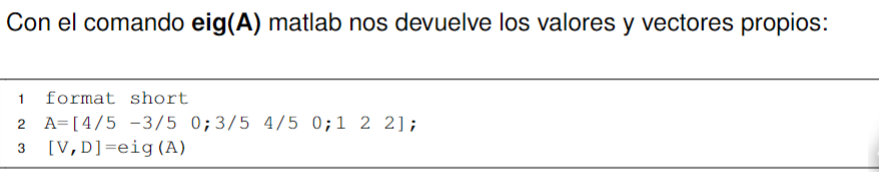

Ejemplo:

%Resolviendo problemas de valores y vectores propios
%para el vector de clasificacion r
clc
A=[0 1 0 1 1;0 0 1 1 1 ; 1 0 0 1 0;0 0 0 0 1;0 0 1 0 0]
[Q,D]=eig(A)
%El primer valor es el unico real, ese es el que necesitamos
evals=diag(D)
vp1=evals(1)
%Encontramos la constante de proporcionalidad alpha
alpha=1/vp1
%Encontramos el vector r como vector propio correspondiente al
%primer valor propio
r=Q(:,1)
%Normalizando el vector de clasificacion
r=r/sum(r)

Ejemplo radios espectrales

A=[10 -1 2 0;-1 11 -1 3;2 -1 10 -1; 0 3 -1 8]
D=diag(diag(A));
L=-tril(A,-1);
U=-triu(A,1);
Tj=inv(D)*(L+U);
Tgs=inv(D-L)*U;
rho_j=max(abs(eig(Tj)))
rho_gs=max(abs(eig(Tgs)))

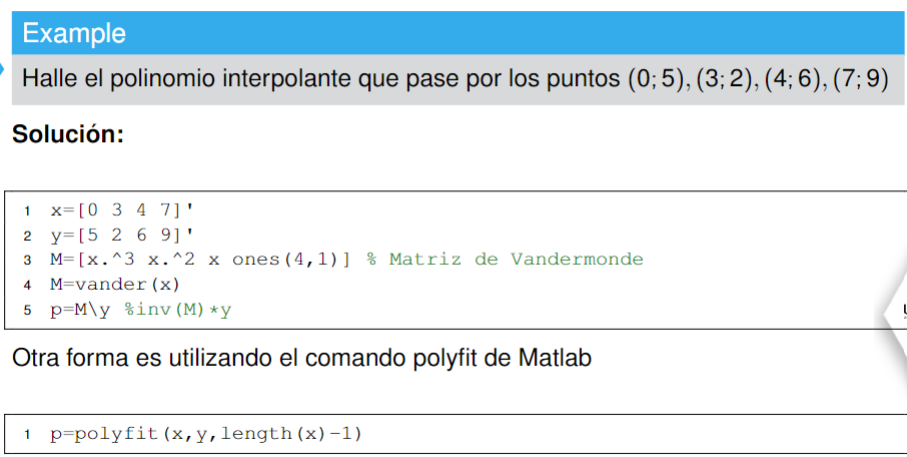

%interpolacion
x=[0 1 3 5 6 7 8]

x =      0     1     3     5     6     7     8


y=[0 6 57 -21121 -45476 790094 8791547]

y =            0           6          57      -21121      -45476      790094     8791547



g1=polyfit(x,y,6) %número de puntos -1

g1 = 1.0e+06 *

   0.002717028769841  -0.057182257142854   0.455637768650764  -1.681320522618933   2.760527402579190  -1.480373420238055   0.000000000000082


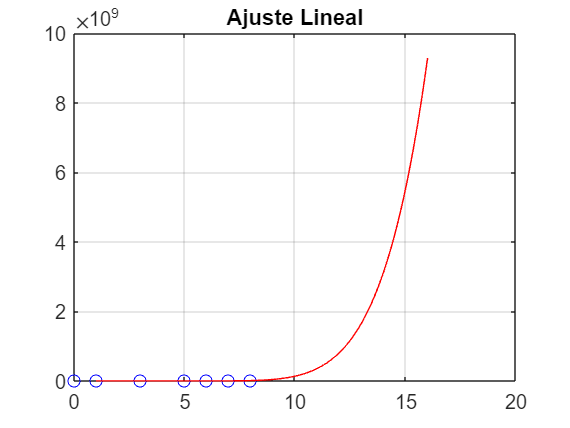

xx=linspace(1,16); % 1<x<16 (eje)
yy=polyval(g1,xx);
plot(x,y,'ob',xx,yy,'r')
grid on
title('Ajuste Lineal')


tiempo=[0 1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20 21 22 23]'

tiempo =      0
     1
     2
     3
     4
     5
     6
     7
     8
     9


temperatura=[20 22 25 28 30 32 33 34 33 31 29 27 25 23 22 21 20 19 20 22 24 26 28 29]'

temperatura =     20
    22
    25
    28
    30
    32
    33
    34
    33
    31



G=tabladif(tiempo,temperatura)

G =                    0  20.000000000000000   2.000000000000000   0.500000000000000  -0.166666666666667                   0   0.016666666666667  -0.008333333333333   0.002777777777778  -0.000768849206349   0.000187389770723  -0.000039958112875   0.000007340267757  -0.000001156572337   0.000000157057449  -0.000000018525254   0.000000001907967  -0.000000000170819   0.000000000012902  -0.000000000000733   0.000000000000013   0.000000000000004  -0.000000000000001   0.000000000000000  -0.000000000000000
   1.000000000000000  22.000000000000000   3.000000000000000                   0  -0.166666666666667   0.083333333333333  -0.033333333333333   0.011111111111111  -0.003373015873016   0.000917658730159  -0.000212191358025   0.000040784832451  -0.000006538600289   0.000000885174496  -0.000000102296109   0.000000010094256  -0.000000000825129   0.000000000048512  -0.000000000000292  -0.000000000000483   0.000000000000098  -0.000000000000014   0.000000000000002  -0.000000000000000               

sum_dif_div=sum(sum(G))

sum_dif_div =      9.071551312171011e+02


coef=polynewton(tiempo,temperatura)

M =                    0  20.000000000000000   2.000000000000000   0.500000000000000  -0.166666666666667                   0   0.016666666666667  -0.008333333333333   0.002777777777778  -0.000768849206349   0.000187389770723  -0.000039958112875   0.000007340267757  -0.000001156572337   0.000000157057449  -0.000000018525254   0.000000001907967  -0.000000000170819   0.000000000012902  -0.000000000000733   0.000000000000013   0.000000000000004  -0.000000000000001   0.000000000000000  -0.000000000000000
   1.000000000000000  22.000000000000000   3.000000000000000                   0  -0.166666666666667   0.083333333333333  -0.033333333333333   0.011111111111111  -0.003373015873016   0.000917658730159  -0.000212191358025   0.000040784832451  -0.000006538600289   0.000000885174496  -0.000000102296109   0.000000010094256  -0.000000000825129   0.000000000048512  -0.000000000000292  -0.000000000000483   0.000000000000098  -0.000000000000014   0.000000000000002  -0.000000000000000               

coef = 1.0e+05 *

  -0.000000000000000   0.000000000000000  -0.000000000000000   0.000000000000000  -0.000000000000017   0.000000000000684  -0.000000000021177   0.000000000518404  -0.000000010192345   0.000000162573221  -0.000002116268899   0.000022540548599  -0.000196365725135   0.001394632202122  -0.008024277287337   0.037036785142737  -0.135193344704901   0.382467133805830  -0.814648617561061   1.251369520301769  -1.294264226819974   0.795729224906634  -0.215671041419156   0.000200000000000


temp_newton=polyval(coef,22.5)

temp_newton =      2.226921950306205e+03


op=0

op =      0


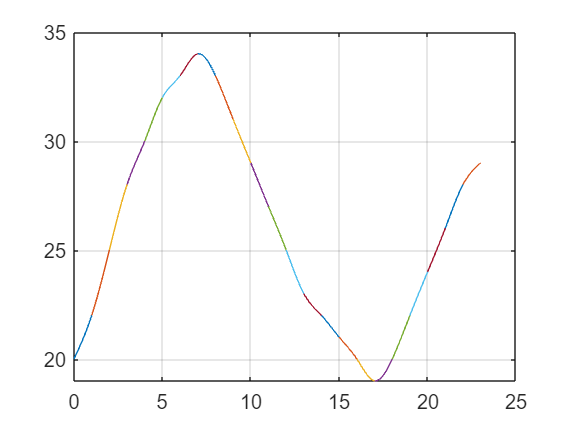

p =    0.247158362609584                   0   1.752841637390416  20.000000000000000
  -0.235791813047918   0.741475087828751   2.494316725219167  22.000000000000000
  -0.303991110417912   0.034099648684997   3.269891461732915  25.000000000000000
   0.451756254719565  -0.877873682568738   2.426117427849174  28.000000000000000
  -0.503033908460349   0.477395081589957   2.025638826870392  30.000000000000000
   0.560379379121830  -1.031706643791090   1.471327264669259  32.000000000000000
  -0.738483608026972   0.649431493574401   1.089052114452571  33.000000000000000
   0.393555052986057  -1.566019330506514   0.172464277520457  34.000000000000000
   0.164263396082745  -0.385354171548344  -1.778909224534401  33.000000000000000
  -0.050608637317036   0.107436016699890  -2.056827379382855  31.000000000000000


p=splinenatural(tiempo',temperatura')

c=p(23,:)

c =    0.267310075810189  -0.801930227430566   1.534620151620377  28.000000000000000


temp_spline= c(1)*(22.5-22)^3+c(2)*(22.5-22)^2+c(3)*(22.5-22)+c(4)

temp_spline =   28.600241278428822


spline(tiempo,temperatura,22.5)

ans =   28.703352368638861


Jacobi

function [z]=jacobi(A,b,x0,Tol)
D=diag(diag(A));
L=-tril(A,-1);
U=-triu(A,1);
Tj=inv(D)*(L+U);
cj=inv(D)*b;
error=1;
z=[x0' error];
while error>Tol
    x1=Tj*x0+cj;
    error=norm(x1-x0,inf)/norm(x1,inf);
    z=[z;x1' error];
    x0=x1;
end
end

Gergshorin?

function []=gershgorin(A)
[m,n]=size(A)
for j=1:n
%(h;k) centro de la circunferencia
    h=abs(A(j,j));
    k=0;
    r=sum(abs(A(j,:)))-abs(A(j,j));
    theta=[0:0.01:2*pi];
    xx=r*cos(theta)+h;
    yy=r*sin(theta)+k;
    plot(xx,yy)
    hold on
end
grid on
end

Método de potencia

function [z]=potencia(A,x0,Maxiter)
z=[x0' 1];
for k=1:Maxiter
    y1=A*x0;
    [maxi,pos]=max(abs(y1));
    u=y1(pos); % valor propio
    x1=y1/u; %vector propio normalizado
    z=[z;x1' u];
    x0=x1;
end
end

Gram Schmidt

function [Q R]=gs_c(A)
[m,n]=size(A);
Q=zeros(m,n);
R=zeros(n);
for j=1:n
    R(1:j-1,j)=Q(:,1:j-1)'*A(:,j);
    temp=A(:,j)-Q(:,1:j-1)*R(1:j-1,j);
    R(j,j)=norm(temp);
    Q(:,j)=temp/R(j,j);
end
end

Gauss Seidel

function [z]=gausseidel(A,b,x0,Tol)
D=diag(diag(A));
L=-tril(A,-1);
U=-triu(A,1);
Tgs=inv(D-L)*U;
cgs=inv(D-L)*b;
error=1;
z=[x0' error];
while error>Tol
    x1=Tgs*x0+cgs;
    error=norm(x1-x0,inf)/norm(x1,inf);
    z=[z;x1' error];
    x0=x1;
end
end

Diagonal dominante

function op=diagdom(A)
%op=0: diagonal estrictamente dominante
 %op=1: No es diagonal estrictamente dominante
[m,n]=size(A)
op=0;
if m==n
    for k=1:m
        if abs(A(k,k))<=sum(abs(A(k,:)))-abs(A(k,k))
            op=1;
            break;
        end
    end
end
end

Método de Lagrange

function p=lagrange(x,y)
n=length(x);
p=zeros(1,n);
for k=1:n
    num=poly(x([1:k-1,k+1:n]));
    den=polyval(num,x(k));
    L=num/den;
    p=p+y(k)*L;
end
end

Método de Newton - Tabla de diferencias divididas

function M=tabladif(x,y)
n=length(x);
M=zeros(n);
M(1:n,1)=y;
for k=1:n-1
    dx=x(k+1:n)-x(1:n-k);
    dy=diff(y)./dx;
    M(1:n-k,k+1)=dy;
    y=dy;
end
M=[x M];
end

Método de Newton - Polinomio interpolante

function p=polynewton(x,y)
M=tabladif(x,y)
n=length(x);
b=M(1,2:end);
p=b(1);
for k=2:n
    p=[0 p]+b(k)*poly(x(1:k-1));
end
end

Spline cúbico natural

function S=splinenatural(X,Y)
N=length(X)-1; H=diff(X); E=diff(Y)./H;
diagprinc=2*(H(1:N-1)+H(2:N)); diagsupinf=H(2:N-1);
g0=0; gn=0;
A=diag(diagprinc)+diag(diagsupinf,1)+diag(diagsupinf,-1);
b=6*diff(E'); g=A\b;
g=[g0 g' gn];
for i=1:N
    S(i,1)=(g(i+1)-g(i))/(6*H(i));
    S(i,2)=g(i)/2;
    S(i,3)= E(i)-H(i)*(g(i+1)+2*g(i))/6;
    S(i,4)=Y(i);
    xx=linspace(X(i),X(i+1),100);
    yy=S(i,1)*(xx-X(i)).^3+S(i,2)*(xx-X(i)).^2+S(i,3)*(xx-X(i))+S(i,4);
    plot(xx,yy), hold on
end
grid on, hold off
end